# Predict Battery State of Charge Using Deep Learning

This example shows how to train a neural network to predict the state of charge of a battery by using deep learning.

Battery state of charge (SOC) is the level of charge of an electric battery relative to its capacity measured as a percentage. SOC is critical information for the vehicle energy management system and must be accurately estimated to ensure reliable and affordable electrified vehicles (xEV). However, due to the nonlinear temperature, health, and SOC dependent behavior of Li-ion batteries, SOC estimation is still a significant automotive engineering challenge. Traditional approaches to this problem, such as electrochemical models, usually require precise parameters and knowledge of the battery composition as well as its physical response. In contrast, using neural networks is a data-driven approach that requires minimal knowledge of the battery or its nonlinear behavior. [1]

This example is based on the MATLAB script from [1]. The example trains a neural network to predict the state of charge of a Li-ion battery, given time series data representing various features of the battery such as voltage, current, temperature, and average voltage and current (over the last 500 seconds). 

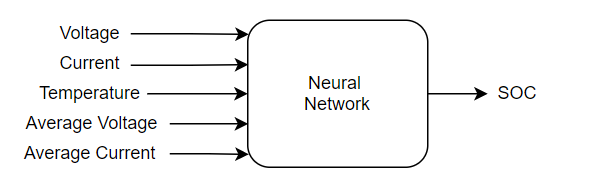

The training data contains a single sequence of experimental data collected while the battery powered an electric vehicle during a driving cycle with an external temperature of 25 degrees Celsius. The test data contains four sequences of experimental data collected during driving cycles at four different temperatures. This example uses the preprocessed data set `LG_HG2_Prepared_Dataset_McMasterUniversity_Jan_2020` from [1]. For an example showing how use a trained neural network inside a Simulink® model to predict the SOC of a battery, see [Battery State of Charge Estimation in Simulink Using Deep Learning Network](docid:nnet_ug#mw_c53557b7-63bf-4221-9e67-a5919361e20f).

## Download Data

Each file in the `LG_HG2_Prepared_Dataset_McMasterUniversity_Jan_2020` data set contains a time series `X` of five predictors (voltage, current, temperature, average voltage, and average current) and a time series `Y` of one target (SOC). Each file represents data collected at a different ambient temperature.

Specify the URL from where to download the data set. Alternatively, you can download this data set manually from [https://data.mendeley.com/datasets/cp3473x7xv/3](https://data.mendeley.com/datasets/cp3473x7xv/3). 

url = "https://data.mendeley.com/public-files/datasets/cp3473x7xv/files/ad7ac5c9-2b9e-458a-a91f-6f3da449bdfb/file_downloaded";

Set `downloadFolder` to where you want to download the ZIP file and the `outputFolder` to where you want to extract the ZIP file.

downloadFolder = tempdir;
outputFolder = fullfile(downloadFolder,"LGHG2@n10C_to_25degC");

Download and extract the `LG_HG2_Prepared_Dataset_McMasterUniversity_Jan_2020` data set.

if ~exist(outputFolder,"dir")
    fprintf("Downloading LGHG2@n10C_to_25degC.zip (56 MB) ... ")
    filename = fullfile(downloadFolder,"LGHG2@n10C_to_25degC.zip");
    websave(filename,url);
    unzip(filename,outputFolder)
end

## Prepare Training Data

For the training data, create a file datastore and specify the read function as the `load` function. The `load` function loads the data from the MAT file into a structure array.

folderTrain = fullfile(outputFolder,"Train");
fdsTrain = fileDatastore(folderTrain,ReadFcn=@load); 

Each file in this datastore contains both the predictors `X` and the targets `Y`.

To create a transformed datastore `dsTrain` that returns the predictor data `X` and the target data Y from each file, transform the file datastore `fdsTrain`.

dsTrain = transform(fdsTrain,@(data) {data.X,data.Y});

Preview the transformed datastore. The output corresponds to a sequence of predictors `X` from the first file and a sequence of targets `Y` from the first file.

preview(dsTrain)

ans = 1×2 cell array
    {5×669956 double}    {1×669956 double}


Note that to input the sequence data from datastores to a deep learning network, the mini-batches of the sequences must have the same length, which usually requires padding the sequences in the datastore. In this example, padding is not necessary because the training data consists of a single sequence. For more information, see [Train Network Using Out-of-Memory Sequence Data](docid:nnet_ug#mw_95e3a847-647e-46d9-8aeb-337c2c273645).

## Prepare Test and Validation Data

For the testing data, create a file datastore and specify the read function as the `load` function. The `load` function loads the data from the MAT file into a structure array.

folderTest = fullfile(outputFolder,"Test");
fdsTest = fileDatastore(folderTest,ReadFcn=@load);

Each file in this datastore contains both the predictors `X` and the targets `Y`.

To create a transformed datastore `tdsPredictorsTest` that returns only the predictor data `X` from each file, transform the file datastore `fdsTest`.

tdsPredictorsTest = transform(fdsTest,@(data) {data.X});

Preview the transformed datastore. The output corresponds to a single sequence of predictors `X` from the first file.

preview(tdsPredictorsTest)

ans = 1×1 cell array
    {5×39293 double}


To create a transformed datastore tdsTargetsTest that returns only the target data Y from each file, transform the file datastore fdsTest.

tdsTargetsTest = transform(fdsTest,@(data) {data.Y});

Preview the transformed datastore. The output corresponds to a single sequence of targets Y from the first file.

preview(tdsTargetsTest)

ans = 1×1 cell array
    {[1 1.0000 1.0000 1.0000 1.0000 1.0000 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9998 0.9998 0.9998 0.9998 0.9998 0.9998 0.9997 0.9996 0.9994 0.9991 0.9989 0.9988 0.9987 0.9983 0.9982 0.9980 0.9980 0.9980 0.9980 0.9981 0.9981 0.9981 0.9981 0.9981 0.9981 0.9980 0.9980 0.9979 0.9978 0.9975 0.9972 0.9970 0.9969 0.9969 0.9969 0.9970 0.9970 0.9970 0.9970 0.9970 0.9968 0.9965 0.9962 0.9960 0.9958 0.9957 0.9956 0.9956 0.9956 0.9955 0.9954 0.9954 0.9954 0.9953 0.9953 0.9952 0.9950 0.9950 0.9950 0.9950 0.9949 0.9948 0.9947 0.9946 0.9946 0.9945 0.9944 0.9942 0.9939 0.9938 0.9936 0.9935 0.9934 0.9933 0.9932 0.9932 0.9931 0.9931 0.9930 0.9929 0.9929 0.9929 0.9929 0.9928 0.9926 0.9925 0.9924 0.9923 0.9923 0.9923 0.9923 0.9923 0.9921 0.9920 0.9918 0.9917 0.9915 0.9914 0.9914 0.9914 0.9915 0.9915 0.9916 0.9916 0.9916 0.9917 0.9917 0.9918 0.9918 0.9918 0.9918 0.9918 0.9918 0.9918 0.9918 0.9917 0.9917 0.9917 0.9917 0.9917 0.9917 0.9917 0.991

Specify the validation data as a subset of the testing data containing only the first file and transform the datastore `fdsVal` to return the predictor data `X` and the target data `Y`.

indices = 1;
fdsVal = subset(fdsTest,indices);
dsVal = transform(fdsVal,@(data) {data.X, data.Y});

## Define Network Architecture

Define the network architecture. Set the number of inputs features to five (voltage, current, temperature, average voltage, and average current).

numFeatures = 5; 

Set the number of output features to one (SOC).

numResponses = 1;

Specify the number of hidden neurons.

numHiddenNeurons = 55; 

Define the layers of the network.

layers = [
    sequenceInputLayer(numFeatures,Normalization="zerocenter")
    fullyConnectedLayer(numHiddenNeurons)
    tanhLayer                            
    fullyConnectedLayer(numHiddenNeurons)
    leakyReluLayer(0.3)                  
    fullyConnectedLayer(numResponses)
    clippedReluLayer(1)                 
    regressionLayer];

Specify the training options. Train for 1200 epochs with mini-batches of size 1 using the "`adam`" solver. To prevent the gradients from exploding, set the gradient threshold to 1. Specify an initial learning rate of 0.01, a learning rate drop period of 400 and a learning rate drop factor of 0.1. Specify a validation frequency of 30. Experiments in Experiment Manager showed that the initial learning rate of 0.01 and the learning rate drop factor of 0.1 together minimize the validation error. For more information on how to optimize hyperparameters using Experiment Manager, see [Choose Training Configurations for LSTM Using Bayesian Optimization](docid:nnet_ug#mw_e8b8c764-32da-4a5c-8143-47f6fd6a8f17).

Epochs = 1200;
miniBatchSize = 1;
LRDropPeriod = 400; 
InitialLR = 0.01;
LRDropFactor = 0.1; 
valFrequency = 30; 

options = trainingOptions("adam", ...                 
    MaxEpochs=Epochs, ...
    GradientThreshold=1, ...
    InitialLearnRate=InitialLR, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropPeriod=LRDropPeriod, ...
    LearnRateDropFactor=LRDropFactor, ...
    ValidationData=dsVal, ...
    ValidationFrequency=valFrequency, ...
    MiniBatchSize=miniBatchSize, ...
    Verbose=0, ...
    Plots="training-progress");

## Train Network

Train the network using `trainNetwork` with the specified training options.

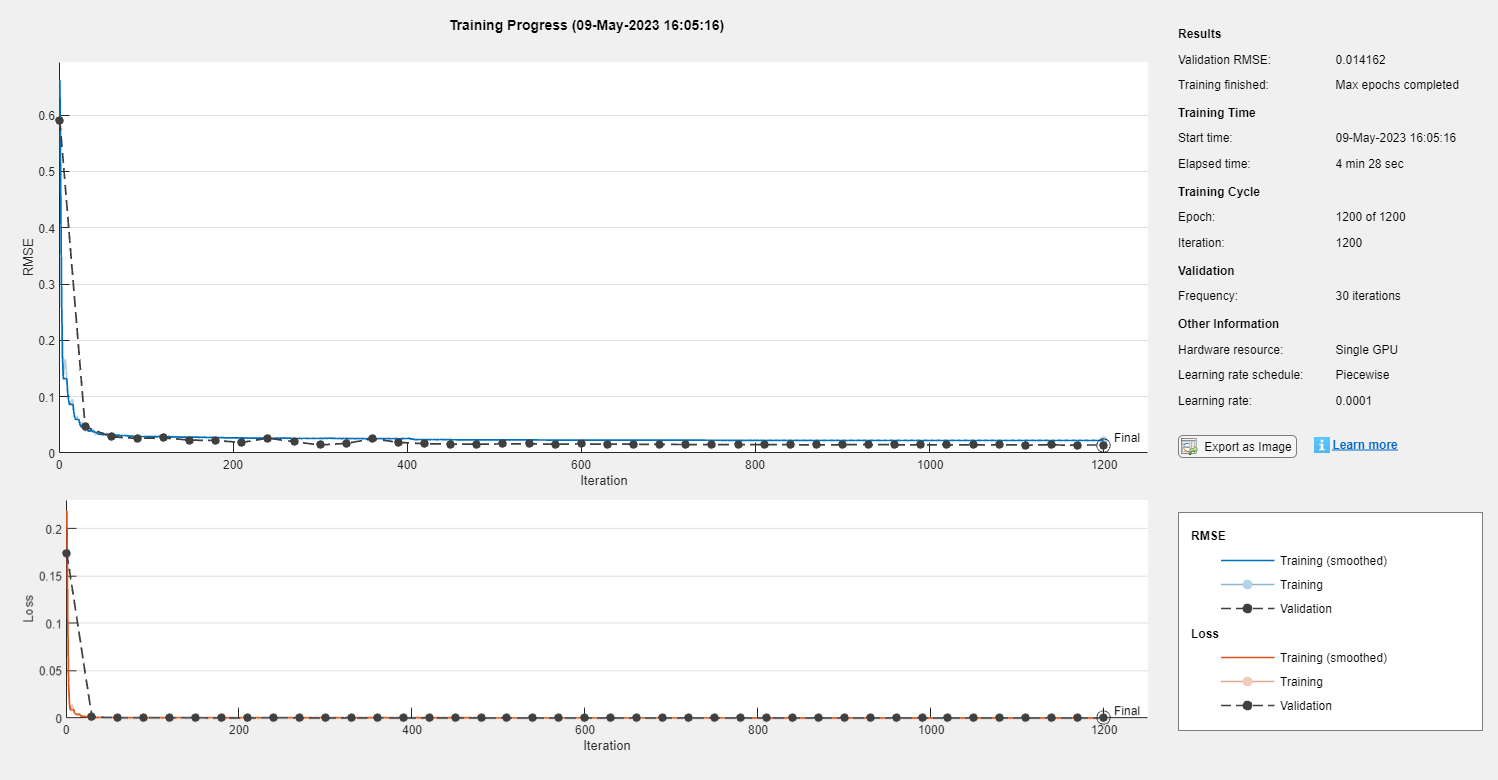

net = trainNetwork(dsTrain,layers,options);

## Test Network

Make predictions on the test data using `predict`. To avoid having to pad the sequences to ensure that all sequences in a mini-batch have the same length, set the mini-batch size to 1.

YPred = predict(net,tdsPredictorsTest,MiniBatchSize=1);

Compare the SOC predicted by the network to the target SOC from the test data for different temperatures.

YTarget = readall(tdsTargetsTest);

Plot the predicted and the target SOC for different ambient temperatures.

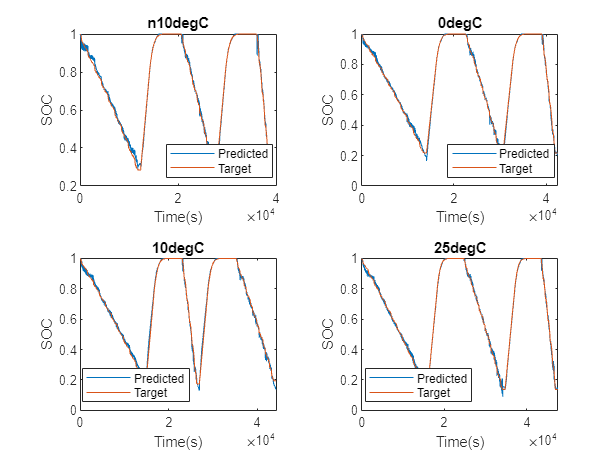

figure

nexttile
plot(YPred{1})
hold on
plot(YTarget{1})
legend(["Predicted" "Target"],Location="Best")
ylabel("SOC")
xlabel("Time(s)")
title("n10degC")

nexttile
plot(YPred{2})
hold on
plot(YTarget{2})
legend(["Predicted" "Target"],Location="Best")
ylabel("SOC")
xlabel("Time(s)")
title("0degC")

nexttile
plot(YPred{3})
hold on
plot(YTarget{3})
legend(["Predicted" "Target"],Location="Best")
ylabel("SOC")
xlabel("Time(s)")
title("10degC")

nexttile
plot(YPred{4})
hold on
plot(YTarget{4})
legend(["Predicted" "Target"],Location="Best")
ylabel("SOC")
xlabel("Time(s)")
title("25degC")

Calculate the error between the predicted SOC and the target SOC for each ambient temperature.

Err_n10degC = YPred{1} - YTarget{1};
Err_0degC = YPred{2} - YTarget{2};
Err_10degC = YPred{3} - YTarget{3};
Err_25degC = YPred{4} - YTarget{4};

Calculate the root mean squared error (RMSE) as a percentage.

RMSE_n10degC = sqrt(mean(Err_n10degC.^2))*100;
RMSE_0degC = sqrt(mean(Err_0degC.^2))*100;
RMSE_10degC = sqrt(mean(Err_10degC.^2))*100;
RMSE_25degC = sqrt(mean(Err_25degC.^2))*100;

Calculate the maximum error as a percentage.

MAX_n10degC = max(abs(Err_n10degC))*100;
MAX_0degC = max(abs(Err_0degC))*100;
MAX_10degC = max(abs(Err_10degC))*100;
MAX_25degC = max(abs(Err_25degC))*100;

Plot the RMSE for the different ambient temperatures.

temp = [-10,0,10,25];
figure
nexttile
bar(temp,[RMSE_n10degC,RMSE_0degC,RMSE_10degC,RMSE_25degC])
ylabel("RMSE (%)")
xlabel("Temperature (C)")

Plot the maximum absolute error for the different ambient temperatures.

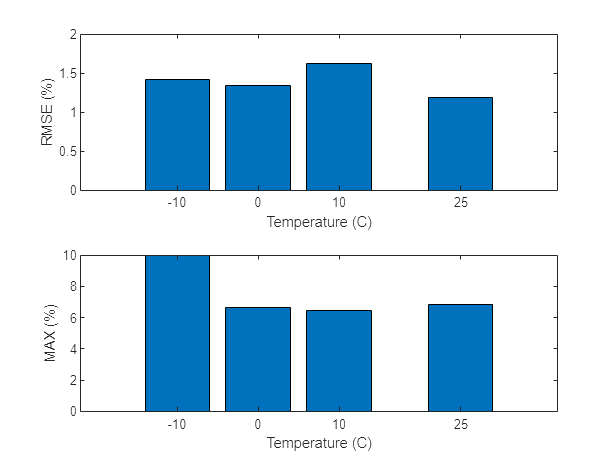

nexttile
bar(temp,[MAX_n10degC,MAX_0degC,MAX_10degC,MAX_25degC])
ylabel("MAX (%)")
xlabel("Temperature (C)")

Lower values in the RMSE and MAX plots indicate more accurate predictions for the corresponding temperatures. Larger values in the same plots indicate less accurate predictions for the corresponding temperatures.

## References

[1] Kollmeyer, Phillip, Carlos Vidal, Mina Naguib, and Michael Skells. “LG 18650HG2 Li-Ion Battery Data and Example Deep Neural Network XEV SOC Estimator Script.” Mendeley, March 5, 2020. https://doi.org/10.17632/CP3473X7XV.3.

*Copyright 2021-2023 The MathWorks, Inc.*